clear
clc
close all

%% ============================================
%  LOAD DATA
%% ============================================
data  = readtable("C:\Users\arigi\Downloads\Merged.csv");

%% ============================================
%  AUTO-DETECT VARIABLE NAMES
%% ============================================
names    = data.Properties.VariableNames;
getVar   = @(pattern) data.(names{find(contains(names, pattern, 'IgnoreCase', true), 1)});

%% ---- BatteryTemp: exclude "max" column -------
btMatches      = find(contains(names, 'BatteryTemp', 'IgnoreCase', true));
btMatches      = btMatches(~contains(names(btMatches), 'max', 'IgnoreCase', true));
batteryTempCol = btMatches(1);

%% ---- SOC: exclude displayed / min / max ------
socMatches = find(contains(names, 'SoC', 'IgnoreCase', true));
socMatches = socMatches( ...
    ~contains(names(socMatches), 'display', 'IgnoreCase', true) & ...
    ~contains(names(socMatches), 'min',     'IgnoreCase', true) & ...
    ~contains(names(socMatches), 'max',     'IgnoreCase', true));
socCol_idx = socMatches(1);

%% ---- extract all variables -------------------
Velocity     = getVar("Velocity");
Elevation    = getVar("Elevation");
Throttle     = getVar("Throttle");
Torque       = getVar("MotorTorque");
Acceleration = getVar("LongitudinalAcceleration");
Regen        = getVar("RegenerativeBraking");
Voltage      = getVar("BatteryVoltage");
Current      = getVar("BatteryCurrent");
BatteryTemp  = data.(names{batteryTempCol});
AmbientTemp  = getVar("AmbientTemp");
AirCon       = getVar("AirCon");
Heater       = getVar("HeaterCurrent");
SOC          = data.(names{socCol_idx});

%% ============================================
%  REMOVE MISSING VALUES
%% ============================================
idx = ~ismissing(Velocity)    & ~ismissing(Elevation)    & ~ismissing(Throttle)    & ...
      ~ismissing(Torque)      & ~ismissing(Acceleration) & ~ismissing(Regen)       & ...
      ~ismissing(Voltage)     & ~ismissing(Current)      & ~ismissing(BatteryTemp) & ...
      ~ismissing(AmbientTemp) & ~ismissing(AirCon)       & ~ismissing(Heater)      & ...
      ~ismissing(SOC);

Velocity     = Velocity(idx);
Elevation    = Elevation(idx);
Throttle     = Throttle(idx);
Torque       = Torque(idx);
Acceleration = Acceleration(idx);
Regen        = Regen(idx);
Voltage      = Voltage(idx);
Current      = Current(idx);
BatteryTemp  = BatteryTemp(idx);
AmbientTemp  = AmbientTemp(idx);
AirCon       = AirCon(idx);
Heater       = Heater(idx);
SOC          = SOC(idx);

%% ============================================
%  FEATURE MATRIX
%% ============================================
X = [Velocity Elevation Throttle Torque Acceleration Regen ...
     Voltage Current BatteryTemp AmbientTemp AirCon Heater];

featureNames = ["Velocity","Elevation","Throttle","Motor Torque","Acceleration","Regen", ...
                "Battery Voltage","Battery Current","Battery Temp","Ambient Temp", ...
                "AirCon","Heater"];

%% ============================================
%  NORMALIZE
%% ============================================
mu    = mean(X, 1);
sigma = std(X, 0, 1);
Xn    = (X - mu) ./ sigma;

%% ============================================
%  PCA
%% ============================================
Xc            = bsxfun(@minus, Xn, mean(Xn, 1));
[V, D]        = eig(cov(Xc));
[latent, ord] = sort(diag(D), 'descend');
coeff         = V(:, ord);
score         = Xc * coeff;
explained     = 100 * latent / sum(latent);

%% ============================================
%  PCA TABLE
%% ============================================
PCA_Table = table(featureNames', coeff(:,1), coeff(:,2), ...
    'VariableNames', {'Feature','PC1_Loading','PC2_Loading'});

disp("PCA Contribution Table")

PCA Contribution Table


disp(PCA_Table)

         Feature         PC1_Loading    PC2_Loading
    _________________    ___________    ___________

    "Velocity"              0.21701       -0.25161 
    "Elevation"           -0.024848        -0.1234 
    "Throttle"              0.41432        -0.0324 
    "Motor Torque"          0.45527        0.10662 
    "Acceleration"           0.4318        0.13766 
    "Regen"                -0.29913       -0.11823 
    "Battery Voltage"      -0.30356        0.14207 
    "Battery Current"      -0.44485       0.019307 
    "Battery Temp"          0.04249       -0.58468 
    "Ambient Temp"         0.021466       -0.46534 
    "AirCon"              -0.070035     -0.0017372 
    "Heater"               0.014747        0.54514 



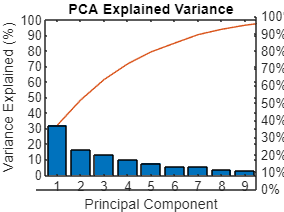


%% ============================================
%  EXPLAINED VARIANCE
%% ============================================
figure
pareto(explained)
title('PCA Explained Variance')
xlabel('Principal Component')
ylabel('Variance Explained (%)')

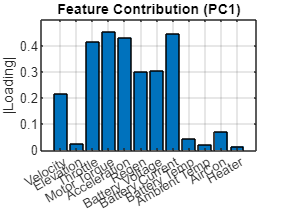


%% ============================================
%  PC1 CONTRIBUTION
%% ============================================
figure
bar(abs(coeff(:,1)))
set(gca, 'XTick', 1:length(featureNames), ...
         'XTickLabel', featureNames, ...
         'XTickLabelRotation', 30)
title("Feature Contribution (PC1)")
ylabel('|Loading|')
grid on

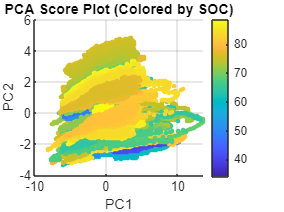


%% ============================================
%  PCA SCATTER
%% ============================================
figure
scatter(score(:,1), score(:,2), 10, SOC, 'filled')
colorbar
xlabel('PC1')
ylabel('PC2')
title('PCA Score Plot (Colored by SOC)')
grid on